# CAPÍTULO 16 - PROBLEMAS DE MAYOR COMPLEJIDAD

Combina compatibilidad, errores de montaje y equilibrio de un elemento rígido, o estudia la transferencia de carga en una unión adhesiva elástica.

Dimensión: barra rígida 2D o plataforma rígida 3D con barras axiales paralelas; además, transferencia adhesiva unidimensional. Las figuras se adaptan a la familia elegida.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

modo="compatibilidad" o "adhesivo". En compatibilidad, posiciones es un vector x para barra plana o una tabla [x y] para plataforma espacial e indica dónde se unen los tirantes a la barra rígida, longitudes y areas sus propiedades, y errores el alargamiento libre o exceso de longitud de montaje. La fuerza P actúa hacia abajo en xCarga: un escalar en barra o [x y] en plataforma. Las varillas son bidireccionales; este modelo no contempla cables flojos ni pandeo.

modo="compatibilidad";
posiciones=[0 0;1 0;1 1;0 1]; longitudes=[1 1 1 1]; areas=[200 200 200 200]*1e-6;
E=210e9; errores=[.0002 -.0001 0 .0001]; P=20000; xCarga=[.5 .5];
longitudUnion=.12; ancho=.03; espesor=.002;
moduloBanda=200e9; rigidezAdhesivo=5e11; fuerzaUnion=1000;

## 2. Compatibilidad de un elemento rígido


$$\delta_i=u+\theta x_i,\qquad N_i=\frac{E_iF_i}{L_i}(\delta_i-\delta_i^0),\qquad \sum N_i=P,\quad\sum N_ix_i=Px_P$$


La barra plana tiene dos movimientos independientes: traslación y giro. La plataforma tiene tres: traslación y dos inclinaciones. Se calculan a partir del equilibrio; las deformaciones de los tirantes respetan esa misma geometría. Un error de montaje puede crear tensiones incluso con P=0.

## 3. Transferencia por adhesivo


$$EFu^{\prime\prime}=bK u,\qquad \beta=\sqrt{\frac{K}{Eh}},\qquad N(0)=0,\quad N(l)=P,\quad \tau=Ku$$


K relaciona tensión tangencial con desplazamiento y se expresa en Pa/m. La banda trabaja axialmente y la base se considera indeformable. Las exponenciales se escriben de forma estable para evitar desbordamientos con uniones largas.

if modo=="compatibilidad"
    resultado=rm_tirantes_rigidos(posiciones,longitudes,areas,E,errores,P,xCarga);
    N=resultado.N;sigma=resultado.sigma;delta=resultado.delta;residuo=resultado.residuo;
    x=resultado.XY(:,1);
    disp(table((1:numel(N))',delta*1000,N/1000,sigma/1e6, ...
        'VariableNames',{'Varilla','delta_mm','N_kN','sigma_MPa'}));
    disp('Residuos de fuerza y primeros momentos:');disp(residuo);
else
    assert(modo=="adhesivo" && all([longitudUnion ancho espesor moduloBanda rigidezAdhesivo]>0),'Union invalida.');
    beta=sqrt(rigidezAdhesivo/(moduloBanda*espesor));
    x=linspace(0,longitudUnion,1001)'; den=-expm1(-2*beta*longitudUnion);
    e1=exp(beta*(x-longitudUnion)); e2=exp(-beta*(x+longitudUnion));
    N=fuerzaUnion*(e1-e2)/den;
    tau=fuerzaUnion*beta/ancho*(e1+e2)/den;
    delta=tau/rigidezAdhesivo;
    residuoTransferencia=trapz(x,tau*ancho)-fuerzaUnion;
    resultado=struct('beta',beta,'N',N,'tau',tau,'u',delta,'residuoTransferencia',residuoTransferencia);
    disp("Cortante maximo del adhesivo [MPa]: "+max(abs(tau))/1e6);
    disp("Residuo de transferencia integrado [N]: "+residuoTransferencia);
end

    Varilla    delta_mm    N_kN    sigma_MPa
    _______    ________    ____    _________

       1        0.26905    2.9       14.5   
       2       0.069048    7.1       35.5   
       3       0.069048    2.9       14.5   
       4        0.26905    7.1       35.5   



Residuos de fuerza y primeros momentos:
   1.0e-11 *

    0.3638
         0
         0



## 4. Resultados gráficos

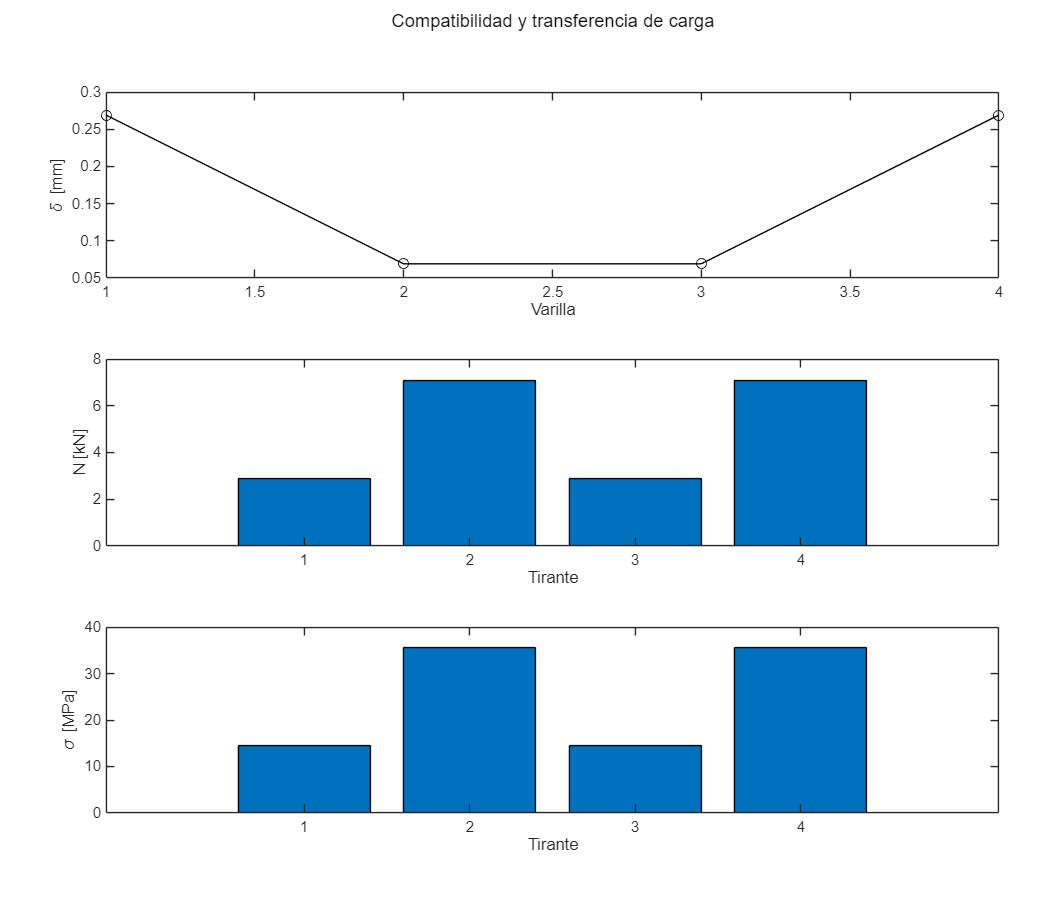

[figura,ejes]=rm_figura(3,'Compatibilidad y transferencia de carga');
if modo=="compatibilidad"
    plot(ejes(1),1:numel(delta),delta*1000,'k-o'); xlabel(ejes(1),'Varilla'); ylabel(ejes(1),'\delta [mm]');
    bar(ejes(2),N/1000); ylabel(ejes(2),'N [kN]'); xlabel(ejes(2),'Tirante');
    bar(ejes(3),sigma/1e6); ylabel(ejes(3),'\sigma [MPa]'); xlabel(ejes(3),'Tirante');
else
    rm_curva(ejes(1),x,N/1000,'N en la banda [kN]');
    rm_curva(ejes(2),x,tau/1e6,'\tau del adhesivo [MPa]');
    rm_curva(ejes(3),x,delta*1000,'u relativo [mm]'); xlabel(ejes(3),'x [m]');
end


$$\delta_i=u+a x_i+b y_i,\qquad \sum N_i=P,\quad\sum N_ix_i=Px_P,\quad\sum N_iy_i=Py_P$$


Una plataforma tiene tres movimientos independientes: traslación vertical y dos inclinaciones. El equilibrio requiere apoyos no alineados. En la barra plana se conserva el modelo de dos movimientos.

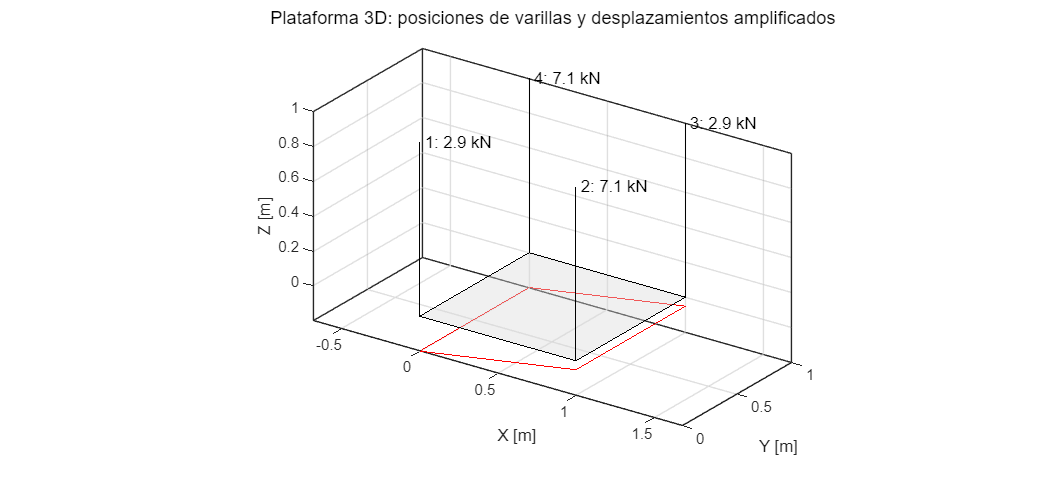

if modo=="compatibilidad" && size(posiciones,2)==2 && size(posiciones,1)>1
    [figura,ejes]=rm_figura(1,'Plataforma 3D: posiciones de varillas y desplazamientos amplificados');hold(ejes(1),'on');
    xy=resultado.XY;escala=.2*max(longitudes)/max(max(abs(delta)),realmin);
    contorno=convhull(xy(:,1),xy(:,2));
    fill3(ejes(1),xy(contorno,1),xy(contorno,2),zeros(size(contorno)),[.85 .85 .85],'FaceAlpha',.4);
    plot3(ejes(1),xy(contorno,1),xy(contorno,2),-delta(contorno)*escala,'r-');
    for j=1:numel(N)
        plot3(ejes(1),[xy(j,1) xy(j,1)],[xy(j,2) xy(j,2)],[0 longitudes(j)],'k-');
        text(ejes(1),xy(j,1),xy(j,2),longitudes(j),sprintf(' %d: %.3g kN',j,N(j)/1000));
    end
    axis(ejes(1),'equal');view(ejes(1),35,24);grid(ejes(1),'on');
    xlabel(ejes(1),'X [m]');ylabel(ejes(1),'Y [m]');zlabel(ejes(1),'Z [m]');
end

## Funciones utilizadas

rm_lineal: resuelve equilibrio con las restricciones indicadas. Aquí obtiene traslación y giro de la barra rígida.

exp: calcula la función exponencial. Aquí describe la transferencia gradual de carga en la unión.

expm1: calcula exp(x)-1 con precisión cerca de cero. Aquí evita pérdida de precisión en uniones de baja rigidez.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Dos familias de problemas avanzados: barra o plataforma rígida suspendida por varillas axiales paralelas y banda adherida a una base rígida mediante una ley de cortante lineal. No es un solucionador universal de todos los problemas avanzados.

Conexión con lo anterior: Reutiliza rigideces EF/L del capítulo 1, geometría compatible del capítulo 2 y equilibrio/energía del capítulo 7.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 16: calculo completado.');

Capitulo 16: calculo completado.
